# Mess- und Regelungstechnik - Praktikum 5

Prof. Dr.-Ing. Anselm Haselhoff - Hochschule Ruhr West

## Vorbereitung

In diesem Praktikum verwenden Sie erstmals Simulink, MATLABs Toolbox zur Simulation von dynamischen Systemen. Für das Praktikum wird die "Simscape" Toolbox benötigt.

Starten Sie Simulink entweder vom Menü "Home" oder mit dem Befehl `simulink`.

Öffnen Sie ein neues "Blank Model".

Sie können nun nach belieben sog. "Blocks" hinzufügen, indem Sie auf der freien Fläche eine Bezeichnung (bspw. *"Resistor"*) über die Tastatur eingeben. Mit der Maus können Blöcke positioniert und verbunden werden. Per Doppelklick können Sie einzelne Blöcke konfigurieren. Eine ausfühlichere Anleitung zum Umgang mit Simulink finden Sie im Moodle-Kurs ("00_Simulink_und_Matlab.pdf

"). 

## Aufgabe 1

### 1)

Bauen Sie die Messschaltung entsprechend Abb. 1 auf.

*Hinweis: Es wurden die elektronischen Bauteile "DC Voltage Source", "Resistor", "Electrical Reference" und "Voltage Sensor" und die Simulink-Komponenten "Solver Configuration", "PS-Simulink-Converter" und "Scope" verwendet.*

*Tipp: Sie können Blöcke mit Strg+R rotieren und Strg+I spiegeln.*

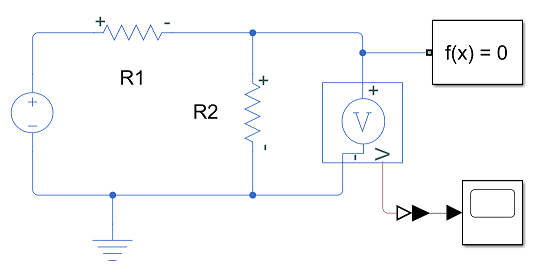

Abbildung 1: Schaltung mit zwei Widerständen

### 2)

Stellen Sie bei der Spannungsquelle eine Spannung von $1V$ und bei R1 und R2 einen Widerstand von $1k\Omega$ bzw. $470\Omega$ ein.

### 3)

Starten Sie die Simulation mit dem grünen "Run"-Button. Betrachten Sie die Messung des Spannugsmessgeräts, indem Sie das Menü des Scopes öffnen und beurteilen Sie den Streckentyp der Schaltung.

### 4)

Bestimme Sie die Parameter für den ausgewählten Typ der Strecke zum einen anhand der gemessenen Sprungantwort und zum anderen rechnerisch mithilfe der Gleichungen, die Sie aus den Grundlagen der Elektrotechnik kennen ("06_Modellbildung_1", S. 19,20). Bringen Sie dazu die Gleichung in die Form der Formeln des P-, PT1- oder PT2-Gliedes aus der Vorlesung (siehe. S. 11, 15, 20 "08_Verhalten_und_Analyse_1").

Streckentyp: linear

**P-Glied:**

0 = u - uR1 - uR2

uR2 = y

0 = u - uR1 - y

uR1 = i * R1

uR2 = i * R2

i = uR2 / R2

uR1 = (uR2 / R2) * R1

uR1 = (y / R2) * R1 

0 = u - (R1 / R2) * y - y

u = (R1 / R2) * y + y

u = y * ((R1 / R2) + 1) 

u = 1V

uR2 = 0,32V

uR1 = u - uR2 = 1V - 0,32V = 0,68V

% Ist das so richtig? P-Glied -> Was ist mt Parameter bestimmen gemeint?
R1 = 1000;
R2 = 470;
y = 0;
u = 0;

### 5)

Verwenden Sie die Funktion `tf` mit den errechneten Parametern aus **1.4)**, um die Übertragungsfunktion des Systems zu erstellen. Plotten Sie das Bodediagramm (`bode`) und die Sprungantwort (`step`) des Frequenzgangs.

%U = Y * ((R1 / R2) + 1);
% G = Y / U;
%G =  1 / ((R1 / R2) + 1);
%Galt = R1 * R2;

## Aufgabe 2

### 1)

Wiederholen Sie **Aufgabe 1** für die Messschaltung aus Abb. 2 mit R = $1k\Omega$ und C = $100\mu F$.

*Hinweis: Es wurde zusätzlich ein "Capacitor" verwendet. MATLAB verwendet ein *$u$* als *$\mu$*.*

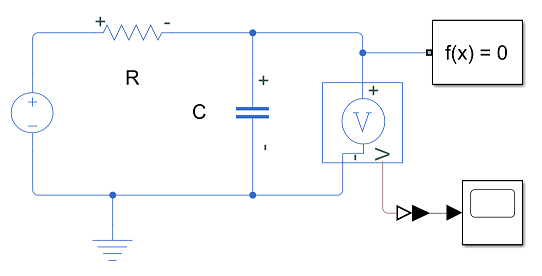

Abbildung 2: RC Schaltung

**PT1-Glied:**

0 = u - uC - uR

uC = y

uR = i * R

uC' = 1 / C * i

i = uC' * C

uR = uC' * C * R

0 = u - uC - uC' * C * R

0 = u - y - y' * C * R

u = R * C * y' + y

Laplace-Trafo:

U = T * s * Y + Y

U = Y * (T * s + 1)

Y / U = 1 / (T * s + 1) = G

numerator = 1;
R = 1000;
C = 0.0001;
T = R * C;
denumerator = [T, 1];
tf(numerator, denumerator)

G = numerator / (T * s + 1)

### 2)

Wiederholen Sie **1.3)** bis **1.5)** erneut mit R = $4.7k\Omega$ und vergleichen Sie die Sprungantworten.

Der Dämpfungsgrad wird durch den neuen Widerstand 

## Aufgabe 3

### 1)

Wiederholen Sie **Aufgabe 1.1** bis **1.3** für die Messschaltung aus Abb. 3 mit R1 = $100\Omega$, C1 = $1mF$, R2 = $1k\Omega$ und C2 = $1mF$. Beachten Sie, dass Sie bei **1.4)** die Parameter nicht mehr an der Sprungantwort ablesen können.

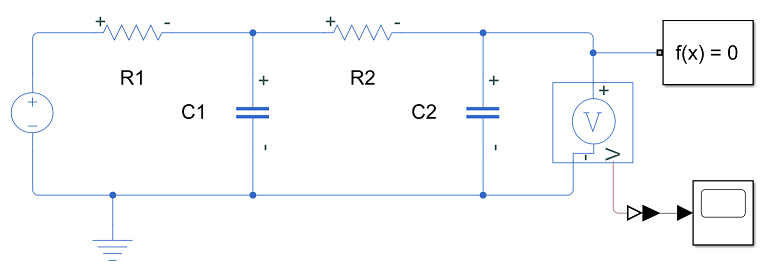

Abbildung 3: RC Tiefpass 2. Grades

**gekoppelte PT1-Glieder -> PT2-Glied**

### 2)

Bestimme Sie die Parameter für den ausgewählten Typ der Strecke rechnerisch mithilfe der Gleichungen, die Sie aus den Grundlagen der Elektrotechnik kennen. Da R1 ≪ R2, kann das Gesamtsystem durch zwei in Serie geschaltete Einzelsysteme aus unabhängigen RC-Tiefpässen 1. Grades *angenähert* werden.

### 3)

Wiederholen Sie **1.5)** für die Messschaltung aus Abb. 3.

*Hinweis: Sie können die Gesamtübertragungsfunktion von zwei seriellen Übertragungsfunktion mit *`series`* bestimmen.*

### 4)

Wiederholen Sie **1.3),** **3.2)** und **1.5)** erneut mit C2 = $0.1mF$ und vergleichen Sie die Sprungantworten.

## Aufgabe 4

### 1)

Wiederholen Sie **Aufgabe 1** für die Messschaltung aus Abb. 4 mit R1 = $1k\Omega$, C1 = $100\mu F$ und L = $500H$. Beachten Sie bei **1.4)**, dass Sie die Parameter nicht mehr aus der Sprungantwort ablesen können.

*Hinweis: Es wurde zusätzlich ein "Inductor" verwendet.*

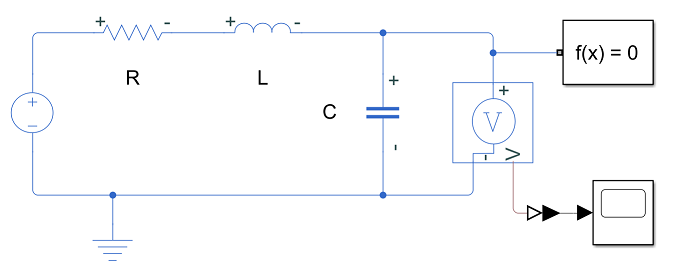

Abbildung 4: RLC Schwingkreis

**PT2-Glied**

### 2)

Wiederholen Sie **1.3)** bis **1.5)** erneut jeweils mit R = $0.5k\Omega$ Und R = $10k\Omega$ und vergleichen Sie die Sprungantworten.